# Replicating an investment strategy

## Goal: investment replica

We consider the following problem:

- There is a secret portfolio, a financial black-blox, which publicly reports its returns on a regular basis (say weekly, monthly, daily);

- We do not know either which instruments the portfolio contains or what weight each instrument has;

- We do know the vast investments vehicles available in the markets, such as bonds and stocks, ETFs, Funds, Futures contracts.

So even if we don't know how the black-box processes the input information, that is, the returns of a large variety of investment instruments, we can see the output of the black-box, i.e., the time series of returns generated by the black-box: our goal is to guess what the inside of the black box looks like.

This means extracting information about **latent variables or functions and structural parameters** from observed information.

This is a dataset of financial data, representing:

- **The HFRX Index, a popular index of Hedge Funds** - see [https://www.hfr.com/indices](https://www.hfr.com/indices) - for those with little or no exposure to Hedge Funds, see [https://en.wikipedia.org/wiki/Hedge_fund](https://en.wikipedia.org/wiki/Hedge_fund); 

- **The MSCI World Index (Global Developed Equities)**, see [https://www.msci.com/acwi](https://www.msci.com/acwi);

- **The MSCI World All Country Index (Global Equities, both Developed and Emerging)**, see [https://www.msci.com/acwi](https://www.msci.com/acwi);

- **The Barclays Bloomberg Global Aggregate Bond Index (Global Bonds, Developed and Emerging, Govt and Corporate)**, see [https://www.bloomberg.com/quote/LEGATRUU:IND](https://www.bloomberg.com/quote/LEGATRUU:IND);

- A broad range of **Futures contracts on equity indices, benchmark bonds, currencies, commodities**.

More specifically, these are the Futures at our disposal:

- RX1 = Bund (10 Yrs Ger)

- CO1 = Brent (Oil)

- DU1 = Schatz (2yrs Gvt Ger)

- ES1 = S&P 500 ( US Equity)

- GC1 = Gold

- LLL1 = MSCI Emerging Markets (EM Equity)

- NQ1 = Nasdaq 100 (Tech Equity)

- TP1 = Topix (Jap. Equity)

- TU2 = 2Yrs US Treasury (US Gvt)

- TY1 = 10Yrs US Treasury (US Gvt)

- VG1 = Eurostoxx 50 (EU Equity)

Other info on this dataset:

- From Bloomberg;

- Weekly data in local currency;

- In the original, raw format (but mostly clean);

- Period = Oct-2007/Apr-2021.

#### "Who replicates what?"

To do a challenging workout with index replication and exploring this kind of analytics, we will try to replicate a "monster index" (that we will build ourselves) consisting literally of tens of thousands of securities at the micro-level. It's a true otherwise non-investable black-box, which practically combines a large part of the stock market, bond and the world of hedge funds, in a multi-currency fashion.

In order to create our clone, we will use Futures contracts (long-short, possibly using leverage). They are cheap (see [https://www.cmegroup.com/trading/equity-index/report-a-cost-comparison-of-futures-and-etfs.html#](https://www.cmegroup.com/trading/equity-index/report-a-cost-comparison-of-futures-and-etfs.html#)), liquid, easy-to-use, and they cover... almost everything (see: [https://www.marketwatch.com/tools/futures).](https://www.marketwatch.com/tools/futures).) We will use a subset of popular Futures contracts. For those with little exposure to finance, see [https://www.cmegroup.com/education/files/a-traders-guide-to-futures.pdf.](https://www.cmegroup.com/education/files/a-traders-guide-to-futures.pdf.)

Of course, alternatively you might replicate:

- The HFRX Hedge Fund Index using Futures contracts (long-short, possibly using leverage);

- The HFRX Hedge Fund Index using MSCI World, MSCI World AC, Barclays Bloomberg Global Aggregate Bond Index, since there are liquid ETFs on those indices (and/or very similar indices);

- We might also replicate MSCI World, MSCI World AC, Barclays Bloomberg Global Aggregate Bond Index using futures contracts.

#### *Load data*

clear all
close all
clc
path = 'InvestmentReplica.mat';
load(path)
Date_ME = XTab.Date(:, :);

The .mat file includes both single variables and a table (for me, sometimes one type of data is more convenient, sometimes the other).

Let's create the "Monster Index": a weighted index (you can specify the weights) made of of MSCI World AC, Barclays Bloomberg Global Aggregate, and HFRX...

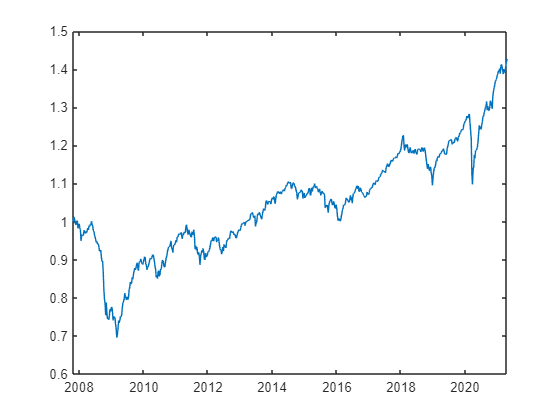

% Synthetic target weights
wHFRXGL = 0.33; 
wMXWO = 0.33;
wLEGATRUU = 0.33;

% Building the target
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = ret2price(y); % "Monster Index" levels

figure
plot(Date_ME,target)

Compute the returns for the Futures contracts. If you look at the time series, they have heterogeneous paths, so it's intuitive that they can be of help, if we want to replicate complex assets, such as our "Monster Index"

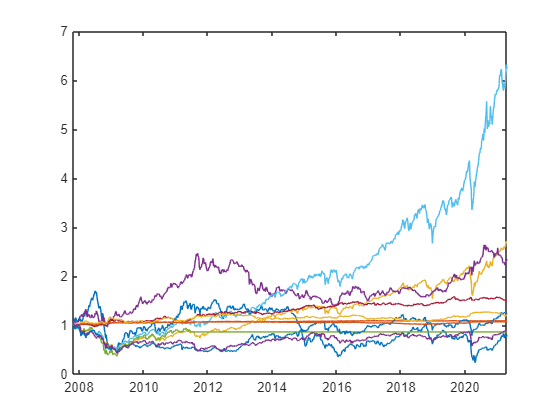

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

figure
plot(Date_ME,ret2price(X))

Define dimensionalities

% Load the return data
portfolioReturns = y;
futuresReturns = X;

n = size(portfolioReturns, 1);  % Number of time steps
m = size(futuresReturns, 2);    % Number of futures

### General theory

**Model:**

 * x(t+1) = F*x(t) + G*u(t) + v1(t)*

*  y(t)   = H*x(t) + D*u(t) + v2(t) *

      where: *v1 ~ N(0,V1)*, *v2 ~ N(0,V2)*, *V12* covariance matrix of *v1* and *v2*

**Kalman-Filter solution:**

  *x_hat(t+1|t) = F*x_hat(t|t-1) + K(t)*e(t)*

*  y_hat(t|t-1) = H*x_hat(t|t-1)*

      where: *e(t) = y(t) - y_hat(t|t-1)*

*             K(t) = (F*P(t)*H' + V12)*(H*P(t)*H' + V2)^-1*

*             P(t+1) = (F*P(t)*F' + V1) - K(t)*(F*P(t)*H' + V12)'*

  and initial conditions are: 

     * x_hat(1|0) = x_0*

*      P(1) = P_0*

### IN OUR CASE:

y = portfolioReturns;
% F = eye(m) so it can be omitted
% G = zeros(m) so the associated term is removed
H = futuresReturns;
% D = 0 so the associated term is removed
V1 = eye(m).*var(futuresReturns); % va cambiato
V2 = 0; % va cambiato
% V12 = 0 so the associated term is removed

**Model:**

  *x(t+1) = x(t) + v1(t)*

*  y(t)   = H*x(t) + v2(t) *

**Kalman-Filter solution:**

 * x_hat(t+1|t) = x_hat(t|t-1) + K(t)*e(t)*

*  y_hat(t|t-1) = H*x_hat(t|t-1)*

      where: *e(t) = y(t) - y_hat(t|t-1)*

*             K(t) = (P(t)*H')*(H*P(t)*H' + V2)^-1*

*             P(t+1) = (P(t) + V1) - K(t)*(P(t)*H')'*


model = InitializeModel(y, [], [], H, [], V1, V2, []);
P = ones(m,m); 
step = 1; % define the rolling windows = one_week*step

tic
[Gain,Weights] = KalmanFilter(model,P,step);
toc

Elapsed time is 0.024803 seconds.


Prediction = sum(futuresReturns.*Weights',2);

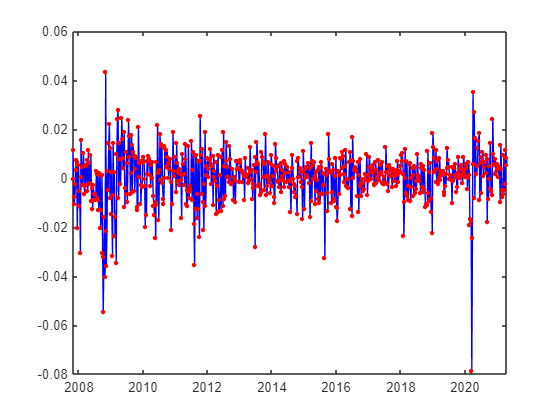

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),sum(futuresReturns.*Weights',2),'r.','MarkerSize',10)

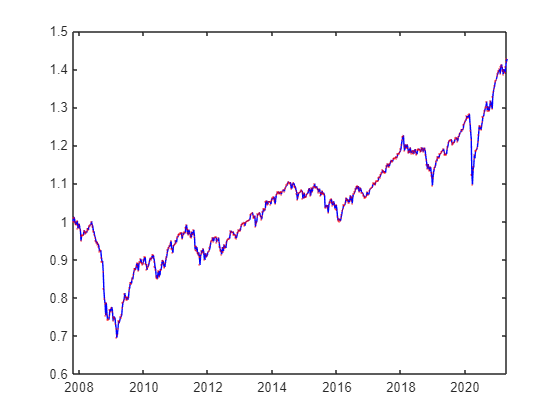


figure()
plot(Date_ME,target,'Color','b')
hold on
plot(Date_ME,ret2price(Prediction),'r.','MarkerSize',1)

### Some financial statistics

#### Tracking Error Volatility (TEV)

Tracking Error = Excess Return = difference between target performance and replica performance.

Tracking Error Volatility = (annualized) standard deviation of Tracking Error.

TE = Prediction - y;
% del rendimento di un portafoglio e del benchmark
TEV = std(TE)*sqrt(52) % lo voglio piccolo

TEV = 1.6822e-17

#### Gross Total Return, and Excess Return (ER)

Even if it is normal for a replica to have a negative excess return,  let's see how negative it is, so we compute the annualized mean Excess Return.

logRClone = diff(log(ret2price(Prediction))); 
logRTarget = diff(log(ret2price(y)));
logTE =  logRClone - logRTarget;
meanTRTarget = exp(mean(logRTarget)*52) - 1

meanTRTarget = 0.0266

meanTRClone = exp(mean(logRClone)*52) - 1

meanTRClone = 0.0266

meanER = exp(mean(logTE)*52) - 1

meanER = 0

#### **Information Ratio (IR)**

The information ratio is similar to the Sharpe Ratio: is a measurement of portfolio returns beyond the returns of a benchmark, compared to the volatility of those returns.

IR = meanER/TEV % Consente di valutare la capacità del gestore di sovra-performare il benchamrk 

IR = 0

% in relazione al rischio assunto

#### Turnover

Sum of the absolute values of the difference in the weights between old and new portfolio, divided by 2; for example: if you have just one asset, and sell it in order to buy another asset - that is, a 100% switch - you have (| `-100% `|  + | +100% |)/2 = 100% which makes sense.

A turnover = 100% per annum means that you sell the entire portfolio.

Turnover = calcTurnover(Weights); % weekly turnover
meanTurnover = mean(Turnover)*52 % average annual turnover

meanTurnover = 2.0261e+03

#### Trading costs (proxy)

A reasonable approximation of explicit trading costs is given by turnover x transaction costs.

tradingCosts = 0.0004; % transaction costs (hp: buyCosts=sellCost)
meanTradingCosts = meanTurnover*tradingCosts

meanTradingCosts = 0.8104

#### Net metrics (proxy)

Let's keep into account explicit trading costs, as a first rough approximation.

NetTR = meanTRClone - meanTradingCosts % transaction costs (hp: buyCosts=sellCost)

NetTR = -0.7838

NetER = meanER - meanTradingCosts

NetER = -0.8104

NetIR = NetER/TEV

NetIR = -4.8176e+16

## R-Squared

% Calculate the residual sum of squares (RSS)
RSS = sum((y - Prediction).^2)

RSS = 3.8312e-33


% Compute the total sum of squares (TSS)
TSS = sum((y - mean(y)).^2)

TSS = 0.0727


% Calculate R-squared
R_squared = 1 - RSS / TSS

R_squared = 1

## Wheights constant in the month as at it beginning

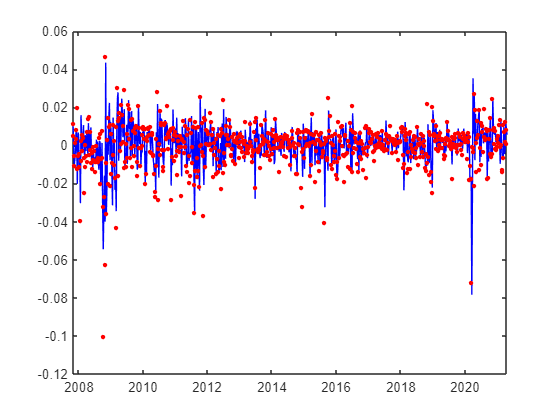

Weights_monthly = Weights;
for i = 2:n
    if Date_ME(i).Month == Date_ME(i-1).Month
        Weights_monthly(:,i) = Weights(:,i-1);
    else
        Weights_monthly(:,i) = Weights(:,i);
    end
end

Prediction = sum(futuresReturns.*Weights_monthly',2);

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),sum(futuresReturns.*Weights_monthly',2),'r.','MarkerSize',10)

% Tracking Error = Excess Return = difference between target performance and replica performance.
TE = Prediction - y;
% Tracking Error Volatility = (annualized) standard deviation of Tracking Error.
TEV = std(TE)*sqrt(52)

TEV = 0.0410

## Find optimal wheights based on Tev

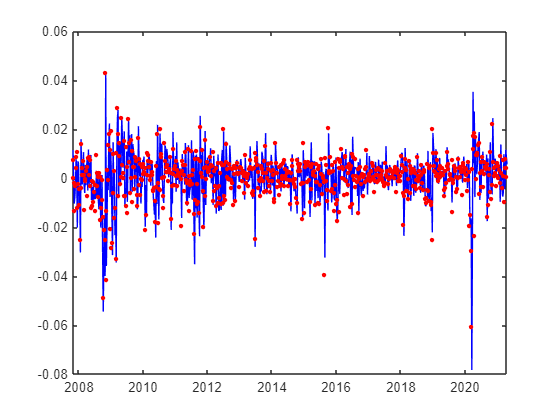

min_TEV = 9999;
for i = 1:n
    TE = sum(futuresReturns*Weights(:,i),2) - y;
    TEV = std(TE)*sqrt(52);
    if TEV < min_TEV
        min_TEV = TEV;
        Weights_constant = Weights(:,i);
    end
end

Prediction = sum(futuresReturns*Weights_constant,2);

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),Prediction,'r.','MarkerSize',10)

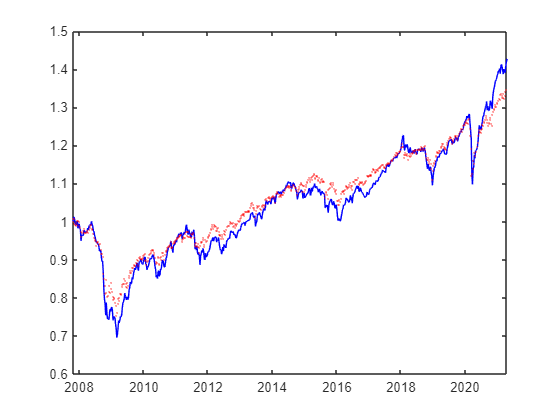

figure()
plot(Date_ME,target,'Color','b')
hold on
plot(Date_ME,ret2price(Prediction),'r.','MarkerSize',1)

% Tracking Error = Excess Return = difference between target performance and replica performance.
TE = Prediction - y;
% Tracking Error Volatility = (annualized) standard deviation of Tracking Error.
TEV = std(TE)*sqrt(52)

TEV = 0.0302